nSquare=3;
n=sqrt(nSquare);
q=1.6*10^-19;
side_length=50*10^-9;
Eg=1.43;
m_not=9.1093837*10^-31 %kg

m_not = 9.1094e-31

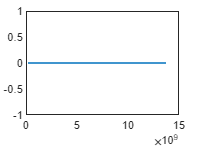

me_eff= 0.067*m_not;
mh_eff= 0.45*m_not;
h_bar=1.0545718*10^-34;
miu=1/((1/me_eff)+1/(mh_eff));
photon_energy=linspace(1.45,3.2,500);
x=photon_energy-Eg;
eta=sqrt((2*miu*side_length*x*q)/((pi^2)*(h_bar^2)));
reduced_energy=eta.^2;
xeta0=0.02;
relative_absorption_0=(1/(xeta0*n.^2)).*exp((-(n./eta-1).^2)./(2*xeta0^2));
plot(reduced_energy,relative_absorption_0);